%Limpieza de pantalla
clear all
close all
clc
% -----  Actividad 2.1 (Parametrización de trayectorias) ---- %
%Ejercicio 1 circulo
fprintf('\n----------\n');


----------


fprintf('Ejercicio 1 circulo');

Ejercicio 1 circulo

fprintf('------------\n');

------------


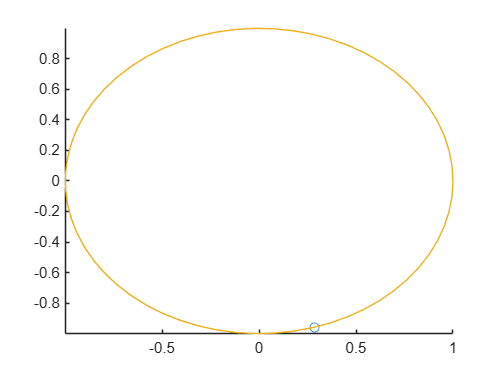

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyecci-on de trayectoria
% [inicio : incremento : fin]
t=[-5:0.1:5];

%Se definen las funciones en 2D
x3=cos(t);
y3=sin(t);
comet (x3,y3)


%Ejercicio 2 ondas

fprintf('\n----------\n');


----------


fprintf('Ejercicio 2 ondas');

Ejercicio 2 ondas

fprintf('------------\n');

------------


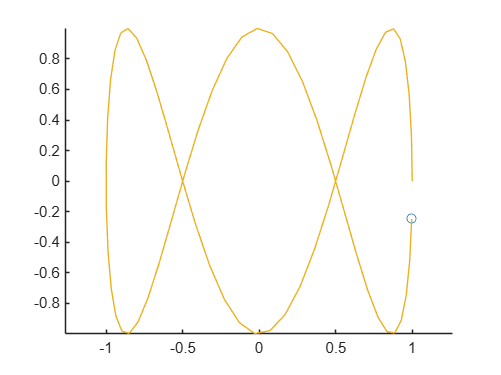

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyecci-on de trayectoria
t = [0:0.1:2*pi];

%Se definen las funciones en 2D
x4 = cos(t);          
y4 = sin(3*t);
comet (x4,y4)
axis equal


%Ejerciio 3 
fprintf('\n----------\n');


----------


fprintf('Ejercicio 3 espirografo');

Ejercicio 3 espirografo

fprintf('------------\n');

------------


%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyecci-on de trayectoria
t=[0:0.001:10*pi];

%Se definen las funciones en 3D
x5= cos(t) + 0.5*cos(20*t)

x5 =     1.5000    1.4999    1.4996    1.4991    1.4984    1.4975    1.4964    1.4951    1.4936    1.4919    1.4900    1.4879    1.4856    1.4831    1.4804    1.4776    1.4745    1.4712    1.4678    1.4642    1.4603    1.4563    1.4521    1.4478    1.4432    1.4385    1.4336    1.4285    1.4232    1.4178    1.4122    1.4065    1.4005    1.3945    1.3882    1.3818    1.3753    1.3685    1.3617    1.3547    1.3476    1.3403    1.3328    1.3253    1.3176    1.3098    1.3019    1.2938    1.2856    1.2773


y6= sin(t) + 0.5*sin(20*t)

y6 =          0    0.0110    0.0220    0.0330    0.0440    0.0549    0.0659    0.0768    0.0877    0.0985    0.1093    0.1201    0.1309    0.1415    0.1522    0.1628    0.1733    0.1837    0.1941    0.2045    0.2147    0.2249    0.2350    0.2450    0.2549    0.2647    0.2744    0.2841    0.2936    0.3030    0.3123    0.3215    0.3306    0.3396    0.3484    0.3571    0.3657    0.3741    0.3825    0.3906    0.3987    0.4066    0.4143    0.4219    0.4294    0.4366    0.4438    0.4508    0.4576    0.4642


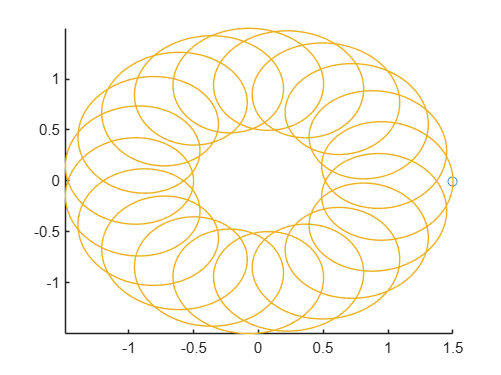

comet (x5,y6)


----
Inciso 1 
-----


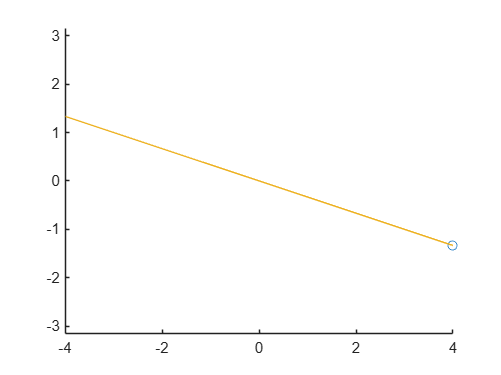


----
Inciso 2 
-----


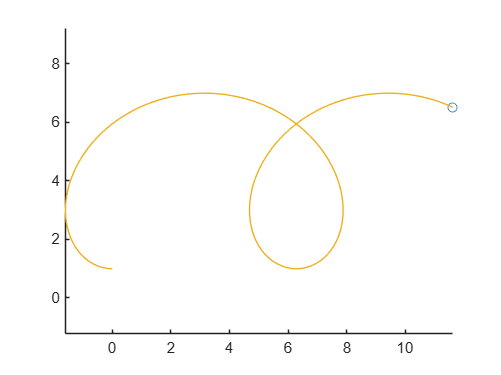


----
Inciso 3 
-----


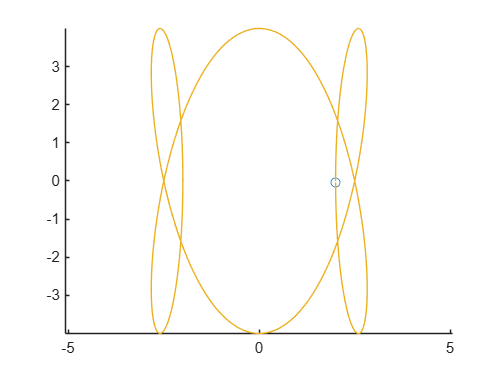


----
Inciso 4 
-----


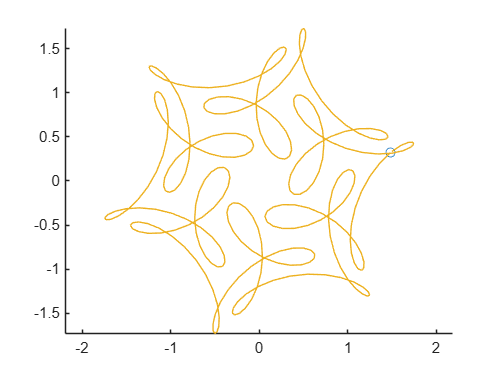


----
Inciso 5 
-----


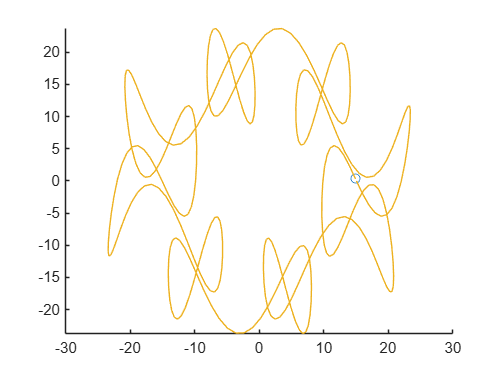


----
Inciso 6 
-----


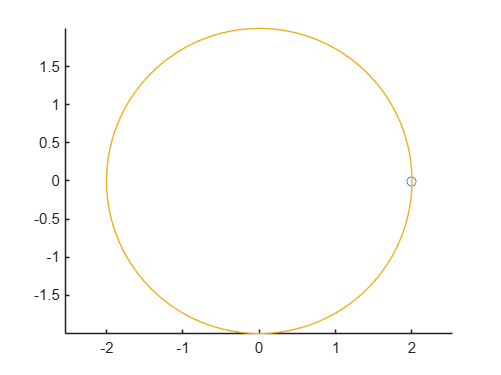


----
Inciso 7 
-----


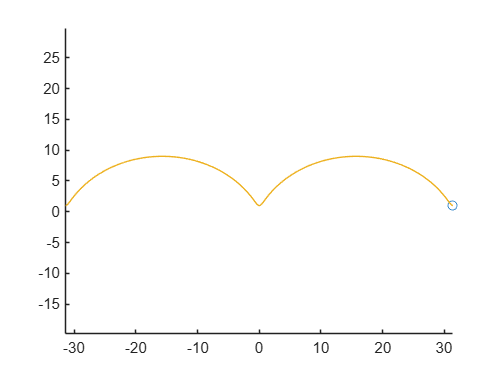


----
Inciso 8 
-----


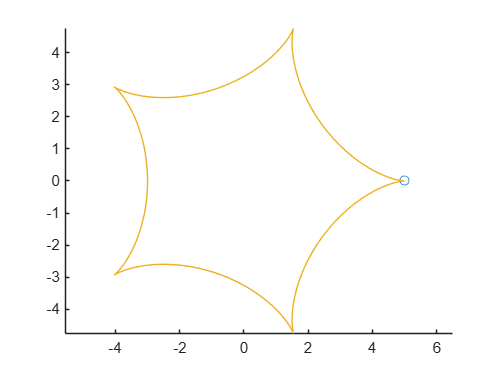


----
Inciso 9 
-----


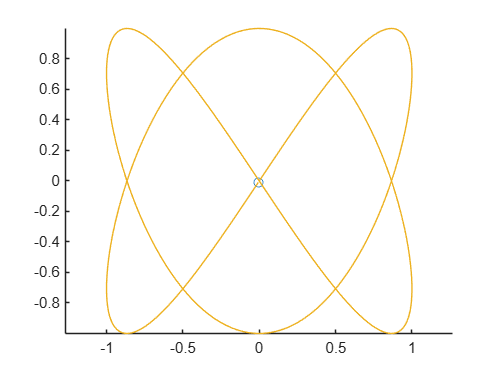


----
Inciso 10 
-----


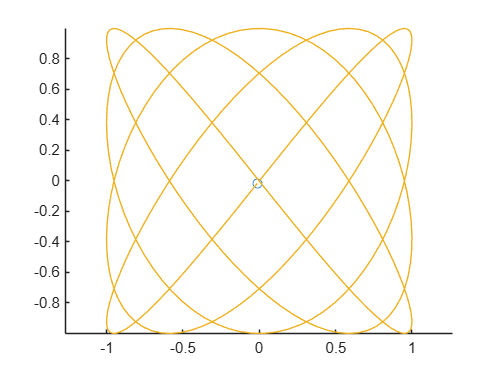


%Obtener las siguientes trayectorias definidas a partir de curvas paramétricas

%config de funciones
%guardamos x(t) y y(t) para cada inciso en una celda {}
funciones_x = {
    @(t) 2*t;                                      %a
    @(t) t - 3*sin(t);                             %b
    @(t) 3*cos(t) - cos(3*t);                      %c
    @(t) cos(t) + 1/2*cos(7*t) + 1/3*sin(17*t);    %d
    @(t) 17*cos(t) + 7*cos(17+7*t);                %e
    @(t) 2*cos(t);                                 %f
    @(t) 5*t - 4*sin(t);                           %g
    @(t) 4*cos(t) + cos(4*t);                      %h
    @(t) sin(2*t);                                 %i
    @(t) sin(4*t)                                  %j
};

funciones_y = {
    @(t) (t - 3*t)/3;                              %a
    @(t) 4 - 3*cos(t);                             %b
    @(t) 4*sin(3*t);                               %c
    @(t) sin(t) + 1/2*sin(7*t) + 1/3*cos(17*t);    %d
    @(t) 17*sin(t) - 7*sin(17*t);                  %e
    @(t) 2*sin(t);                                 %f
    @(t) 5 - 4*cos(t);                             %g
    @(t) 4*sin(t) - sin(4*t);                      %h
    @(t) sin(3*t);                                 %i
    @(t) sin(5*t)                                  %j
};

%rangos de t para cada inciso
intervalos = {
    [-2, 2]; [0, 10]; [0, 2*pi]; [0, 2*pi]; [0, 2*pi]; 
    [0, 14*pi]; [-2*pi, 2*pi]; [0, 2*pi]; [0, 2*pi]; [0, 2*pi]
};

%for
for i = 1:length(funciones_x)
    fprintf('\n----\nInciso %d \n-----\n', i);
    
    %definir el tiempopara el inciso
    limites = intervalos{i}; %usar losintervalos
    t = limites(1) : 0.02 : limites(2); %paso 
    
    %evaluar funciones
    x = funciones_x{i}(t);
    y = funciones_y{i}(t);
    
    %graficas
    figure(i); %figure(1); 
    comet(x, y); 
    axis equal;
end